# GPS Demo - Gator Summer 2022

### REV A

GPS Demo to drive Gator from Camp Bravo to Camp Charlie loop and back to Camp Bravo in Parcel B.

%%% Path Declaration
addpath(...
    "ACT\",...
    "SENSE\",...
    "SETUP\",...
    "SHUTDOWN\",...
    "THINK\",...
    "TESTING\",...
    "SIMULATION\",...
    "RTK_GPS\")
disp("FOLDER PATHS ADDED")

FOLDER PATHS ADDED


Found Start 1


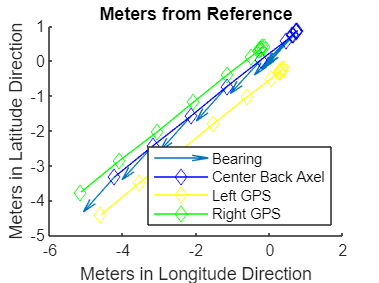

%%% SETUP GPS MAP 
GPStoFront=0.762;% midpoint GPS to front of car
GPStoback=1;% midpoint GPS to back of car
FronttoBack=GPStoback+GPStoFront;
[waypoints,lat1new,lon1new,lat2new,lon2new, middlelatref,middlelonref]=ConfigureWaypoint("RTK_GPS\GPS_Right_Forest_True.ubx","RTK_GPS\GPS_Left_Forest_True.ubx",GPStoback);

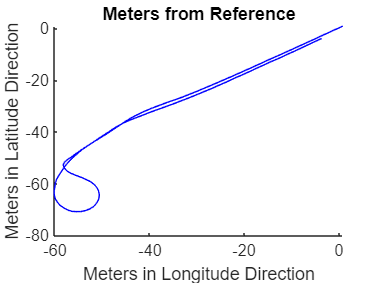

 clf
 start=1;
 section=size(lat1new,2);
 hold on
  title("Meters from Reference")
     xlabel('Meters in Longitude Direction') 
    ylabel('Meters in Latitude Direction') 
 plot(waypoints(start:section,2),waypoints(start:section,1),'-b');
 hold off

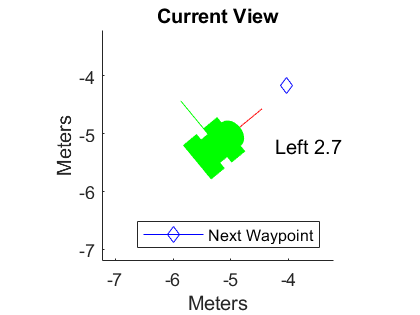

END


%%%simulation
% Variable Setup
clf
wayStep=15;
firstwaysttep=wayStep;
 start=wayStep-1;
controlFlag=1;
time=200;
gpsData = struct( ...
             "lon1", lon1new(1,start),...
             "lat1", lat1new(1,start),...
             "lon2", lon2new(1,start),...
             "lat2", lat2new(1,start)...
             );

[CurrentPosHead]= ReferencePoint(middlelatref,middlelonref,gpsData,GPStoback);
firstCurrentPosHead=CurrentPosHead;
Datafromrun=eye(time,3);
f=figure;
while (controlFlag < time)           % loop for number of elements in t
    % Think
    [motorControls, wayStep]=thinkPathB2C(CurrentPosHead, waypoints, wayStep,FronttoBack);


    % End-of-path checker
   if wayStep>size(waypoints,1)
        disp("END")
        break 
   end
   updateplot(CurrentPosHead,motorControls,waypoints,wayStep,f)

    [CurrentPosHead] = SimulateSense(CurrentPosHead,motorControls,FronttoBack);
    Datafromrun(controlFlag,:)=[CurrentPosHead.X;CurrentPosHead.Y;motorControls.steer];
    controlFlag=controlFlag+1;
    
end 

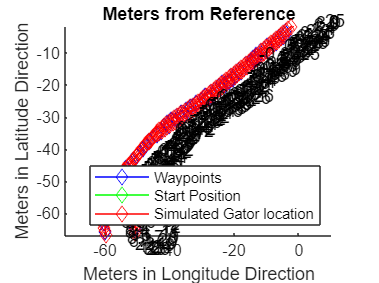

% 
clf
title("Meters from Reference")
 xlabel('Meters in Longitude Direction') 
ylabel('Meters in Latitude Direction') 
hold on
    plot(waypoints(firstwaysttep:end,2),waypoints(firstwaysttep:end,1),'-bd'); % add '-bd' to add points
    plot(firstCurrentPosHead.X,firstCurrentPosHead.Y,'-gd')
     plot(Datafromrun(:,1),Datafromrun(:,2),'-rd')
     text(Datafromrun(:,1),Datafromrun(:,2),num2str(Datafromrun(:,3),2))
 legend({'Waypoints','Start Position','Simulated Gator location'},'Location','southeast')
axis equal
hold off

%setupGPSDemo(Mega,GPS1,GPS2);
objects1 = setupGPSDemo('COM7','COM5','COM6');

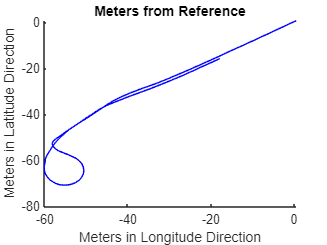

%%% MAIN
%%%simulation
% Variable Setup
clf
wayStep=15;
 start=wayStep-1;
 section=wayStep+120;
controlFlag=1;
%plotting

f1=figure;
%create array to hold data from run
Datafromrun=eye(5*60*20,3);
%inital voltage
motorControls.throttle=0;
motorControls.steer=0;
% oldmotorControls  = struct( ...
%     "throttle", [],...
%     "steer",[]);
actGPS(objects1.Mega, motorControls)

Unable to resolve the name objects1.Mega.

%oldmotorControls=motorControls

disp("Turn on Linear Actuators") 
pause
% Main Loop
while (controlFlag > 0)           % loop for number of elements in t
    % Sense
    senseobjects = sense(objects1);

    % Think
    [CurrentPosHead]= ReferencePoint(middlelatref,middlelonref,senseobjects.gpsData,GPStoback)
     [motorControls, wayStep]=thinkPathB2C(CurrentPosHead,waypoints, wayStep,FronttoBack);
    
    %Plotting
    updateplot(CurrentPosHead,motorControls,waypoints,wayStep,f1)

    % Act
    actGPS(objects1.Mega, motorControls);

    % End-of-path checker
    if wayStep>size(waypoints,1)
        disp("END")
        motorControls.throttle=-1;
        actGPS(objects1.Mega, motorControls)
        break 
    end

    % Update MotorControls
    %oldmotorControls=motorControls; 

    %Save data
     Datafromrun(controlFlag,:)=[CurrentPosHead.X;CurrentPosHead.Y;motorControls.steer];

    controlFlag=controlFlag+1;
end 

clf
title("Meters from Reference")
 xlabel('Meters in Longitude Direction') 
ylabel('Meters in Latitude Direction') 
hold on
    plot(waypoints(firstwaysttep:end,2),waypoints(firstwaysttep:end,1),'-bd'); % add '-bd' to add points
    plot(firstCurrentPosHead.X,firstCurrentPosHead.Y,'-gd')
     plot(Datafromrun(:,1),Datafromrun(:,2),'-rd')
     text(Datafromrun(:,1),Datafromrun(:,2),num2str(Datafromrun(:,3),2))
 legend({'Waypoints','Start Position','Simulated Gator location'},'Location','southeast')
axis equal
hold off

%%% SHUTDOWN
clear